# Create Table Entries That Span Multiple Rows

Use the Row`Span` property to specify that a table entry spans multiple rows.

Create a presentation.

import mlreportgen.ppt.*
ppt = Presentation("myRowSpan.pptx");
open(ppt);

Add a slide to the presentation.

slide = add(ppt,"Title and Table");

Create a table that has three columns.

t = Table(3);
t.Style = [t.Style {VAlign("middleCentered")}];

Create the first table row.

tr1 = TableRow();

Create an entry in the first column that spans all four rows.

tr1te1 = TableEntry("Header Column");
tr1te1.RowSpan = 4;
append(tr1,tr1te1);

Create an entry in the second column that spans the first two rows.

tr1te2 = TableEntry("Subheader 1");
tr1te2.RowSpan = 2;
append(tr1,tr1te2);

Create an entry in the third column that spans one row.

append(tr1,TableEntry("entry(1,1)"));
append(t,tr1);

Create the second table row. Create the third column entry. The first and second column entries are already defined because the first and second column entries span the first two rows.

tr2 = TableRow();
append(tr2,TableEntry("entry(2,1)"));
append(t,tr2);

Create the third table row and create the entries for the second and third columns. Make the second column entry span two rows. The first column entry is already defined because the row one, column one entry spans all of the rows. 

tr3 = TableRow();
tr3te2 = TableEntry("Subheader 2");
tr3te2.RowSpan = 2;
append(tr3,tr3te2);
append(tr3,TableEntry("entry(3,1)"));
append(t,tr3);

Create the fourth table row. Create the entry for only the third column. The first and second column entries are already defined by previous rows that span multiple columns.

tr4 = TableRow();
append(tr4,TableEntry("entry(4,1)"));
append(t,tr4);

Add a title and the table to the slide.

replace(slide,"Title","Table Entry That Spans Multiple Rows");
replace(slide,"Table",t);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the slide in the generated presentation:

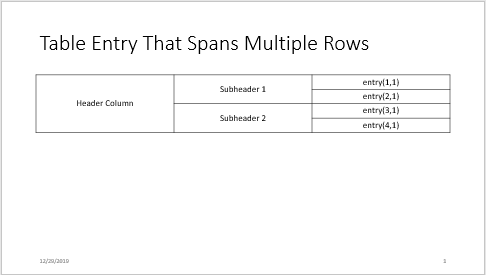

*Copyright 2019 The MathWorks, Inc.*